clc
clear

### Base joint transformation matrices

index_base_transf = [0.99543,0.0948317,0.0112118,-334.764;
                    -0.0948257,0.995493,-0.00106805,127.194;
                    -0.0112626,0,0.999937,35.8849;
                     0,0,0,1]

index_base_transf =     0.9954    0.0948    0.0112 -334.7640
   -0.0948    0.9955   -0.0011  127.1940
   -0.0113         0    0.9999   35.8849
         0         0         0    1.0000


middle_base_transf = [0.999946,0.00816771,0.0063473,-329.135;
                     -0.00781971,0.998562,-0.0530405,107.25;
                     -0.00677139,0.052988,0.998572,40.0239;
                      0,0,0,1]

middle_base_transf =     0.9999    0.0082    0.0063 -329.1350
   -0.0078    0.9986   -0.0530  107.2500
   -0.0068    0.0530    0.9986   40.0239
         0         0         0    1.0000


ring_base_transf = [0.992946,-0.118401,0.0062789,-323.383;
                    0.118567,0.991535,-0.0529187,87.6131;
                    0,0.0532899,0.998579,34.6232;
                    0,0,0,1]

ring_base_transf =     0.9929   -0.1184    0.0063 -323.3830
    0.1186    0.9915   -0.0529   87.6131
         0    0.0533    0.9986   34.6232
         0         0         0    1.0000


little_base_transf = [0.976155,-0.21698,0.00634951,-313.459;
                      0.217008,0.974728,-0.0530368,68.2337;
                      0.00531891,0.0531501,0.998572,33.3454;
                      0,0,0,1]

little_base_transf =     0.9762   -0.2170    0.0063 -313.4590
    0.2170    0.9747   -0.0530   68.2337
    0.0053    0.0532    0.9986   33.3454
         0         0         0    1.0000


thumb_base_transf = [0.478786,0.608523,0.632823,-245.412;
                    -0.874059,0.398032,0.278553,116.47;
                    -0.0823778,-0.686491,0.722457,24.4594;
                     0,0,0,1]

thumb_base_transf =     0.4788    0.6085    0.6328 -245.4120
   -0.8741    0.3980    0.2786  116.4700
   -0.0824   -0.6865    0.7225   24.4594
         0         0         0    1.0000


### More transformation matrices


$$(x,y) \mapsto (x,0,y)$$


A = [1, 0;
     0, 0;
     0, 1];


$$(x,y,z) \mapsto 10(-x,y,z)$$


B = [-1, 0, 0;
     0, 1, 0;
     0, 0, 1] * 10;


$$(x,y,z,1) \mapsto 0.1(x,y,z)$$


C = [1, 0, 0, 0;
     0, 1, 0, 0;
     0, 0, 1, 0] * 0.1;

### Hand simulation

interp_table = readmatrix('interp_table.xlsx');
model_data = readtable('linkage_model_data.xlsx');

interp_theta1 = readmatrix('theta1-inverse-mapping-500x500.xlsx').';
interp_theta1_ = readmatrix('theta1_-inverse-mapping-500x500.xlsx').';

% inputs
steps = 100;

x_index_disp  = 0.99;
x_middle_disp = 0.99;
x_ring_disp   = 0.99;
x_little_disp = 0.99;
x_thumb_disp  = 0.99;
xf_thumb_disp = 0.50;

x_index_max  = 26.2;
x_middle_max = 22.9;
x_ring_max   = 25.1;
x_little_max = 27.6;
x_thumb_max  = 23.9;
xf_thumb_max = 22.6;

x_index  = linspace(0, x_index_disp * x_index_max, steps)

x_index =          0    0.2620    0.5240    0.7860    1.0480    1.3100    1.5720    1.8340    2.0960    2.3580    2.6200    2.8820    3.1440    3.4060    3.6680    3.9300    4.1920    4.4540    4.7160    4.9780    5.2400    5.5020    5.7640    6.0260    6.2880    6.5500    6.8120    7.0740    7.3360    7.5980    7.8600    8.1220    8.3840    8.6460    8.9080    9.1700    9.4320    9.6940    9.9560   10.2180   10.4800   10.7420   11.0040   11.2660   11.5280   11.7900   12.0520   12.3140   12.5760   12.8380


x_middle = linspace(0, x_middle_disp * x_middle_max, steps)

x_middle =          0    0.2290    0.4580    0.6870    0.9160    1.1450    1.3740    1.6030    1.8320    2.0610    2.2900    2.5190    2.7480    2.9770    3.2060    3.4350    3.6640    3.8930    4.1220    4.3510    4.5800    4.8090    5.0380    5.2670    5.4960    5.7250    5.9540    6.1830    6.4120    6.6410    6.8700    7.0990    7.3280    7.5570    7.7860    8.0150    8.2440    8.4730    8.7020    8.9310    9.1600    9.3890    9.6180    9.8470   10.0760   10.3050   10.5340   10.7630   10.9920   11.2210


x_ring   = linspace(0, x_ring_disp * x_ring_max, steps)

x_ring =          0    0.2510    0.5020    0.7530    1.0040    1.2550    1.5060    1.7570    2.0080    2.2590    2.5100    2.7610    3.0120    3.2630    3.5140    3.7650    4.0160    4.2670    4.5180    4.7690    5.0200    5.2710    5.5220    5.7730    6.0240    6.2750    6.5260    6.7770    7.0280    7.2790    7.5300    7.7810    8.0320    8.2830    8.5340    8.7850    9.0360    9.2870    9.5380    9.7890   10.0400   10.2910   10.5420   10.7930   11.0440   11.2950   11.5460   11.7970   12.0480   12.2990


x_little = linspace(0, x_little_disp * x_little_max, steps)

x_little =          0    0.2760    0.5520    0.8280    1.1040    1.3800    1.6560    1.9320    2.2080    2.4840    2.7600    3.0360    3.3120    3.5880    3.8640    4.1400    4.4160    4.6920    4.9680    5.2440    5.5200    5.7960    6.0720    6.3480    6.6240    6.9000    7.1760    7.4520    7.7280    8.0040    8.2800    8.5560    8.8320    9.1080    9.3840    9.6600    9.9360   10.2120   10.4880   10.7640   11.0400   11.3160   11.5920   11.8680   12.1440   12.4200   12.6960   12.9720   13.2480   13.5240


x_thumb  = linspace(0, x_thumb_disp * x_thumb_max, steps)

x_thumb =          0    0.2390    0.4780    0.7170    0.9560    1.1950    1.4340    1.6730    1.9120    2.1510    2.3900    2.6290    2.8680    3.1070    3.3460    3.5850    3.8240    4.0630    4.3020    4.5410    4.7800    5.0190    5.2580    5.4970    5.7360    5.9750    6.2140    6.4530    6.6920    6.9310    7.1700    7.4090    7.6480    7.8870    8.1260    8.3650    8.6040    8.8430    9.0820    9.3210    9.5600    9.7990   10.0380   10.2770   10.5160   10.7550   10.9940   11.2330   11.4720   11.7110


xf_thumb = linspace(0, xf_thumb_disp * xf_thumb_max, steps)

xf_thumb =          0    0.1141    0.2283    0.3424    0.4566    0.5707    0.6848    0.7990    0.9131    1.0273    1.1414    1.2556    1.3697    1.4838    1.5980    1.7121    1.8263    1.9404    2.0545    2.1687    2.2828    2.3970    2.5111    2.6253    2.7394    2.8535    2.9677    3.0818    3.1960    3.3101    3.4242    3.5384    3.6525    3.7667    3.8808    3.9949    4.1091    4.2232    4.3374    4.4515    4.5657    4.6798    4.7939    4.9081    5.0222    5.1364    5.2505    5.3646    5.4788    5.5929


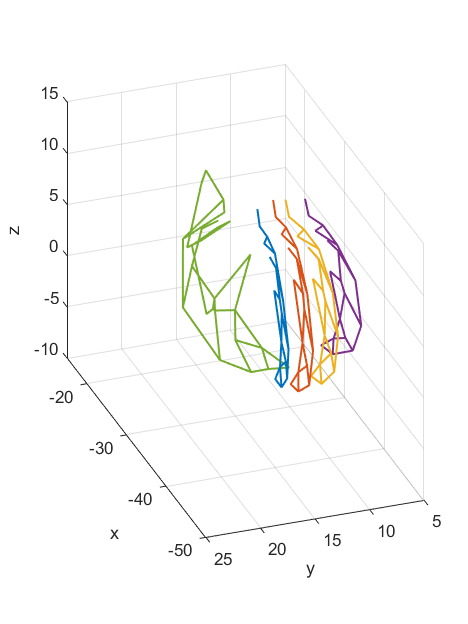

r = ones([1 33]);
r1 = ones([1 47]);
f = figure();
[title_inputs,axes_title_inputs,legend_inputs] = plot_defaults(f,9.9,13.2,14,14,12);
for i = 1:steps
    index_pose  = C * index_base_transf * [B*A * get_index_pose(x_index(i), interp_table, model_data); r];
    middle_pose = C * middle_base_transf * [B*A * get_middle_pose(x_middle(i), interp_table, model_data); r];
    ring_pose   = C * ring_base_transf * [B*A * get_ring_pose(x_ring(i), interp_table, model_data); r];
    little_pose = C * little_base_transf * [B*A * get_little_pose(x_little(i), interp_table, model_data); r];
    thumb_pose  = C * thumb_base_transf * [10 * get_thumb_pose(x_thumb(i),xf_thumb(i),interp_theta1,interp_theta1_,model_data); r1];
    plot3(index_pose(1,:), index_pose(2,:), index_pose(3,:), ...
          middle_pose(1,:), middle_pose(2,:), middle_pose(3,:), ...
          ring_pose(1,:), ring_pose(2,:), ring_pose(3,:), ...
          little_pose(1,:), little_pose(2,:), little_pose(3,:), ...
          thumb_pose(1,:), thumb_pose(2,:), thumb_pose(3,:), 'LineWidth', 1.2);
    xlim([-50 -15]);
    ylim([5 25]);
    zlim([-10 15]);
    daspect([1 1 1]);
    grid on
    %view([-70 28]);
    view([-110 28]);
    %view([-1 0 0]);
    xlabel('x');
    ylabel('y');
    zlabel('z');
    pause(0.05);
end

%exportgraphics(f,'final_pose.png','Resolution',600);

index_pose
middle_pose
ring_pose
little_pose
thumb_pose